# Approximate High-Fidelity UAV model with UAV Guidance Model block

Simulation models often need different levels of fidelity during different development stages. During the rapid-prototyping stage, we would like to quickly experiment and tune parameters to test different autonomous algorithms. During the production development stage, we would like to validate our algorithms against models of increasing fidelities. In this example, we demonstrate a method to approximate a high-fidelity model with the [UAV Guidance Model](docid:uav_ref.mw_646d746b-9b4d-4f96-9463-f42cbaa5d228) block and use it to prototype and tune a waypoint following navigation system. See [Tuning Waypoint Follower for Fixed-Wing UAV](docid:uav_ug#mw_e63e2589-2766-4217-baf6-cdfa41c9da0d). The same navigation system is tested against a high-fidelity model to verify its performance.

The example model uses a high-fidelity unmanned aerial vehicle (UAV) model consisting of a plant model and a mid-level built-in autopilot. This model contains close to a thousand blocks and it is quite complicated to work with. As a first step in the development process, we created a variant system that can switch between this high-fidelity model and the UAV Guidance Model block. The high-fidelity model is extracted from a File Exchange entry, [Simulink Drone Reference Application](https://www.mathworks.com/matlabcentral/fileexchange/67625-simulink-drone-reference-application).

## UAV model of different fidelity

uavModel = 'FixedWingModel.slx';
open_system(uavModel);

You can switch between the low and high-fidelity models by changing a MATLAB® variable value stored in the data dictionary associated with this model.

plantDataDictionary = Simulink.data.dictionary.open('pathFollowingData.sldd');
plantDataSet = getSection(plantDataDictionary,'Design Data');

% Switch to high-fidelity model
assignin(plantDataSet,'useHighFidelity',1);

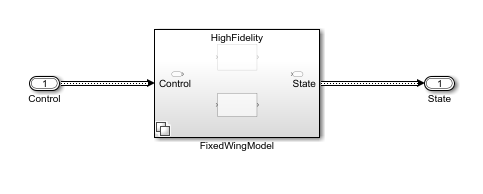

% Switch to low-fidelity model
assignin(plantDataSet,'useHighFidelity',0);

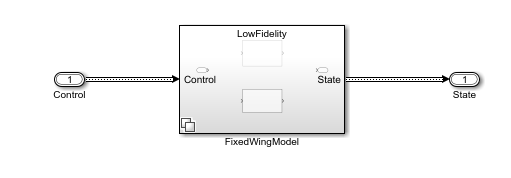

## Approximate high-fidelity fixed-wing model with low-fidelity guidance model

To approximate the high-fidelity model with the UAV Guidance Model block, create step control signals to feed into the model and observe the step response to `RollAngle`, `Height`, and `AirSpeed` commands.

stepModel = 'stepResponse';
open_system(stepModel)

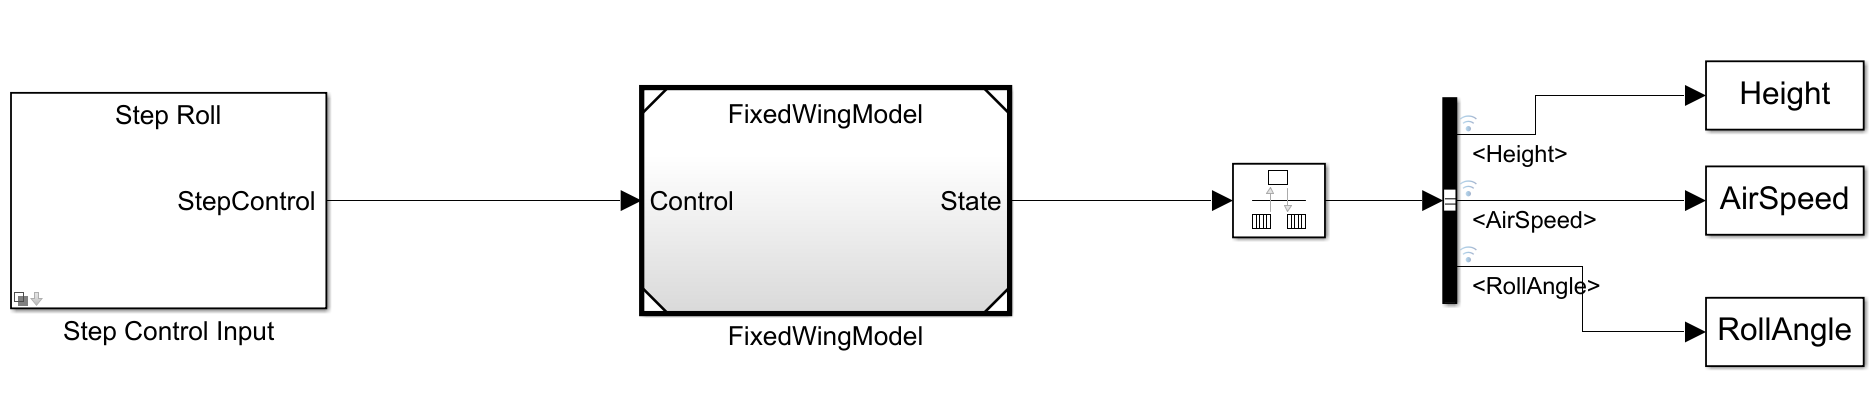

First, command a change in roll angle.

controlBlock = get_param('stepResponse/Step Control Input','Object');
controlBlock.StepControl = 'RollAngle Step Control';

assignin(plantDataSet,'useHighFidelity',1);

sim(stepModel);
highFidelityRollAngle = RollAngle.Data(:);
highFidelityTime = RollAngle.Time;

figure()
plot(highFidelityTime, highFidelityRollAngle,'--r');
title('Roll Angle Step Response')

Zooming into the simulation result above, you see the characteristics of the roll angle controller built into the high-fidelity model. The settling time for the roll angle is close to 2.5 seconds.

xlim([75 80])
ylim([-0.1 0.548])

For a second-order PD controller, to achieve this settling time with a critically damped system, the following gains should be used to configure the UAV Guidance Model block inside the low-fidelity variant of the UAV model. For this example, the **UAV Guidance Model** block is simulated using code generation to increase speed for multiple runs. See the block parameters.

zeta = 1.0; % critically damped
ts = 2.5; % 2 percent settling time
wn = 5.8335/(ts*zeta);
newRollPD = [wn^2 2*zeta*wn];

Set the new gains and simulate the step response for the low-fidelity model. Compare it to the original response.

load_system(uavModel)
set_param('FixedWingModel/FixedWingModel/LowFidelity/Fixed Wing UAV Guidance Model',...
    'PDRollFixedWing',strcat('[',num2str(newRollPD),']'))
save_system(uavModel)

assignin(plantDataSet, 'useHighFidelity', 0);

sim(stepModel);

lowFidelityRollAngle = RollAngle.Data(:);
lowFidelityTime = RollAngle.Time;

hold on;
plot(lowFidelityTime, lowFidelityRollAngle,'-b');
legend('High-Fidelity Response', 'Low-Fidelity Response', 'Location','southeast');

The low-fidelity model achieves a similar step response. Similarly, we can tune the other two control channels: `Height` and `AirSpeed`. More sophisticated methods can be used here to optimize the control gains instead of visual inspection of the control response. Consider using System Identification Toolbox® to perform further analysis of the high-fidelity UAV model behavior.

controlBlock.StepControl = 'AirSpeed Step Control';
assignin(plantDataSet, 'useHighFidelity', 0);

sim(stepModel);
lowFidelityAirSpeed = AirSpeed.Data(:);
lowFidelityTime = AirSpeed.Time;

assignin(plantDataSet, 'useHighFidelity', 1);

sim(stepModel);
highFidelityAirSpeed = AirSpeed.Data(:);
highFidelityTime = AirSpeed.Time;

figure()
plot(lowFidelityTime, lowFidelityAirSpeed,'-b');
hold on;
plot(highFidelityTime, highFidelityAirSpeed,'--r');
legend('Low-Fidelity Response', 'High-Fidelity Response', 'Location','southeast');
title('Air Speed Step Response')
xlim([70 80])
ylim([17.5 19.2])

controlBlock.StepControl = 'Height Step Control';
assignin(plantDataSet, 'useHighFidelity', 0);

sim(stepModel);
lowFidelityHeight = Height.Data(:);
lowFidelityTime = Height.Time;

assignin(plantDataSet, 'useHighFidelity', 1);

sim(stepModel);
highFidelityHeight = Height.Data(:);
highFidelityTime = Height.Time;

figure()
plot(lowFidelityTime, lowFidelityHeight,'-b');
hold on;
plot(highFidelityTime, highFidelityHeight,'--r');
legend('Low-Fidelity Response', 'High-Fidelity Response', 'Location','southeast');
title('Height Step Response')
xlim([70 150])
ylim([49 56])

## Test navigation algorithm with low-fidelity model

Now that we have approximated the high-fidelity model with the **UAV Guidance Model** block, we can try to replace it with the UAV Guidance Model block in the [Tuning Waypoint Follower for Fixed-Wing UAV](docid:uav_ug#mw_e63e2589-2766-4217-baf6-cdfa41c9da0d) example. Test the effect of the lookahead distance and heading control gains against these models of different fidelities.

navigationModel = 'pathFollowing';
open_system(navigationModel);

assignin(plantDataSet,'useHighFidelity',0);

sim(navigationModel);

figure
visualizeSimStates(simStates);

## Validate with high-fidelity model

assignin(plantDataSet,'useHighFidelity',1);

sim(navigationModel);

figure
visualizeSimStates(simStates);

## Conclusion

This example shows how we can approximate a high-fidelity model with a low-fidelity abstraction of a fixed-wing UAV. The opposite approach can be used as well to help with choosing autopilot control gains for the high-fidelity model. You can first decide acceptable characteristics of an autopilot control response by simulating a low-fidelity model in different test senarios and then tune the high-fidelity model autopilot accordingly.

discardChanges(plantDataDictionary);
clear plantDataSet
clear plantDataDictionary
close_system(uavModel, 0);
close_system(stepModel, 0);
close_system(navigationModel, 0);

*Copyright 2018-2020 The MathWorks, Inc.*